# Road-Load Resisting Force of Vehicle 1D Basic Model

Copyright 2021 The MathWorks, Inc.

This Live Script collects block parameter values from Vehcle 1D Basic block and plots the road-load resisting force. Make sure you have selected the block in Simulink canvas before running this script.

% Get parameter values from the block.
% Make sure you have selected the vehicle block before running this script.
block_info = Vehicle1DBasic_get_block_info(gcbh)

block_info = struct with fields:
             M_e_kg: 1790
           R_tire_m: 0.3000
             A_rl_N: 175
     B_rl_N_per_kph: 0
    C_rl_N_per_kph2: 0.0320
      grav_m_per_s2: 9.8100


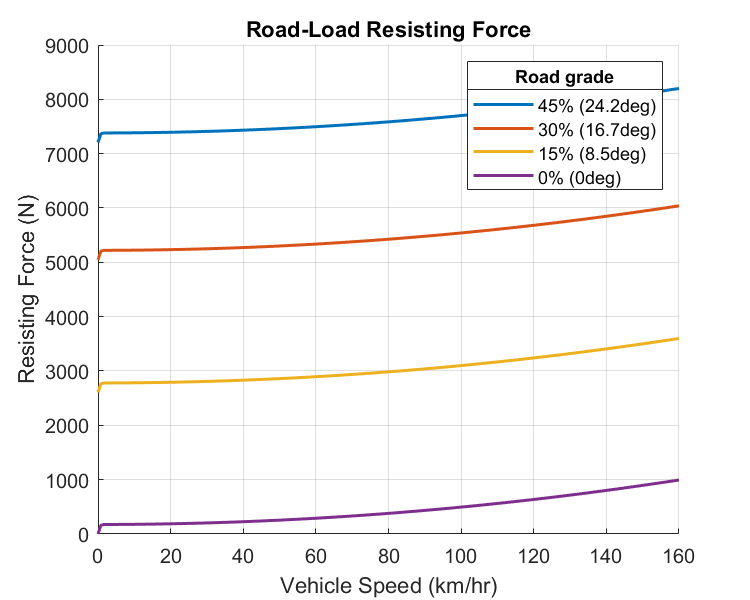

fig = Vehicle1DBasic_plot_resisting_force( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 160, 200), ...
  "RoadGradeVector_pct", [45, 30, 15, 0] );
fig.Position(3:4) = [500 400];  % width height